This scrip is to use to find the best-fitted time step between simulation and experiment.

pls change the **simMSDType** variable, and input the **expMSDData** manually(C:\Users\zhouquan\OneDrive\research\scrips\processed_data).

V1spline

We try to use spline instead of customed function(a*t^b+c) to get a more resonable timestep.

V2splineCompare

comparing several MSD

pnValue='p';
epDistance=47;
expMSDName=[pnValue,num2str(epDistance)];
expMSDType=[pnValue,num2str(epDistance),' 0.05DifferenceDiscard'];
load(['C:\Users\zhouquan\OneDrive\research\polychrom simulation\newProcessedData\mixed data ',expMSDType,'.mat']);
residual_2d_list=[];
residual_min_list=[];
b_min_list=[];
sim_list=[];
MSDmultiplier=1e-18*(340*epDistance/100)^2;
if epDistance==47
    aSlantWell=2;
elseif epDistance==77
    aSlantWell=1.27;
elseif epDistance==179
    aSlantWell=0.63;
end
simParameterList=[0.28:0.005:0.3];
simMSDType=['V1=1000(r-',num2str(aSlantWell),'); V2=kr^2'];
%simMSDType=['V1=1000(r-',num2str(aSlantWell),'); V2=k\cdot(re-rp)^2'];
for simParameter=simParameterList
    load(['MSD of newTwoStage V1(x,y,z)=1000(r-',num2str(aSlantWell),');V2=',num2str(simParameter),'r^2 n=1,100,N=100,Ne=1000,timestep=1000vLt 2023-03-19 13.mat'])
    %load(['MSD of SpringBondTwoStage V1(x,y,z)=1000(r-',num2str(aSlantWell),');V2=',num2str(simParameter),'(re-rp)^2 n=1,100,N=100,Ne=1000,timestep=500vLt 2023-03-31.mat'])

    spFunction=spline(average_time_list,MSD_average);
    %figure
    %plot(average_time_list,MSD_average);

    t_exp=t_mixMSD(1,:);
    MSD_exp=t_mixMSD(2,:);
    b_scale_delta=1;
    b_scale_min=100;
    b_scale_max=1000;
    if 1000<average_time_list(end)/max(t_exp)
        b_scale=b_scale_min:b_scale_delta:b_scale_max;
    else
        b_scale=b_scale_min:b_scale_delta:average_time_list(end)/max(t_exp);
    end
    %b_scale=[1,2,5,10,100,200,500,1000,2e3,5e3,1e4,2e4,5e4,1e5];
    residual_list=[];
    residual_min=1e100;
    for b=b_scale
        residual=0;
        for t=1:length(t_exp)
            residual=residual+(MSDmultiplier*(ppval(spFunction,t_exp(t)*b))-MSD_exp(t)*1e-18)^2;
        end
        %select the min residual b
        if residual<=residual_min
            b_min=b;
            residual_min=residual;
        end
        residual_list=[residual_list,residual];
        
    end
    %b_min=1e2;
    %b_min=100000;
    t=1:max(t_exp)/100:max(t_exp);
    
    sim_list=[sim_list;MSDmultiplier*ppval(spFunction,t*b_min)];
    
    residual_min_list=[residual_min_list;residual_min];
    b_min_list=[b_min_list;b_min];
    residual_2d_list=[residual_2d_list;residual_list];
    
    
end

residual figure

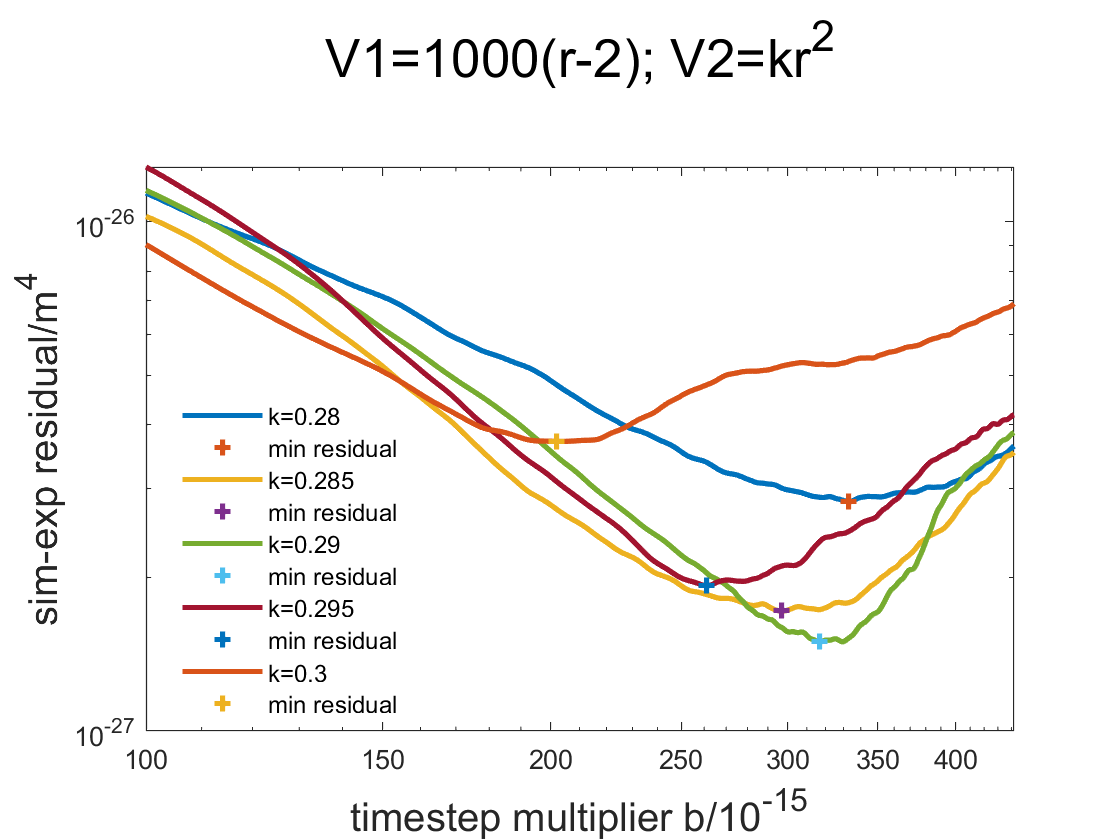

figure
%subplot(1,2,1)
hold on
box on
for simParameterNumber=1:length(simParameterList)
    plot(b_scale,residual_2d_list(simParameterNumber,:),'LineWidth',2,'DisplayName',['k=',num2str(simParameterList(simParameterNumber))])
    plot(b_min_list(simParameterNumber),residual_min_list(simParameterNumber),'+','LineWidth',2,'DisplayName','min residual')
end
title({simMSDType;''},"FontSize",20)
legend("Location","best")
legend("boxoff")
set(gca,'xscale','log')
set(gca,'yscale','log')
xlabel('timestep multiplier b/10^{-15}',"FontSize",15)
ylabel('sim-exp residual/m^4',"FontSize",15)

show the exp MSD and sim MSD

first calculate sim MSD

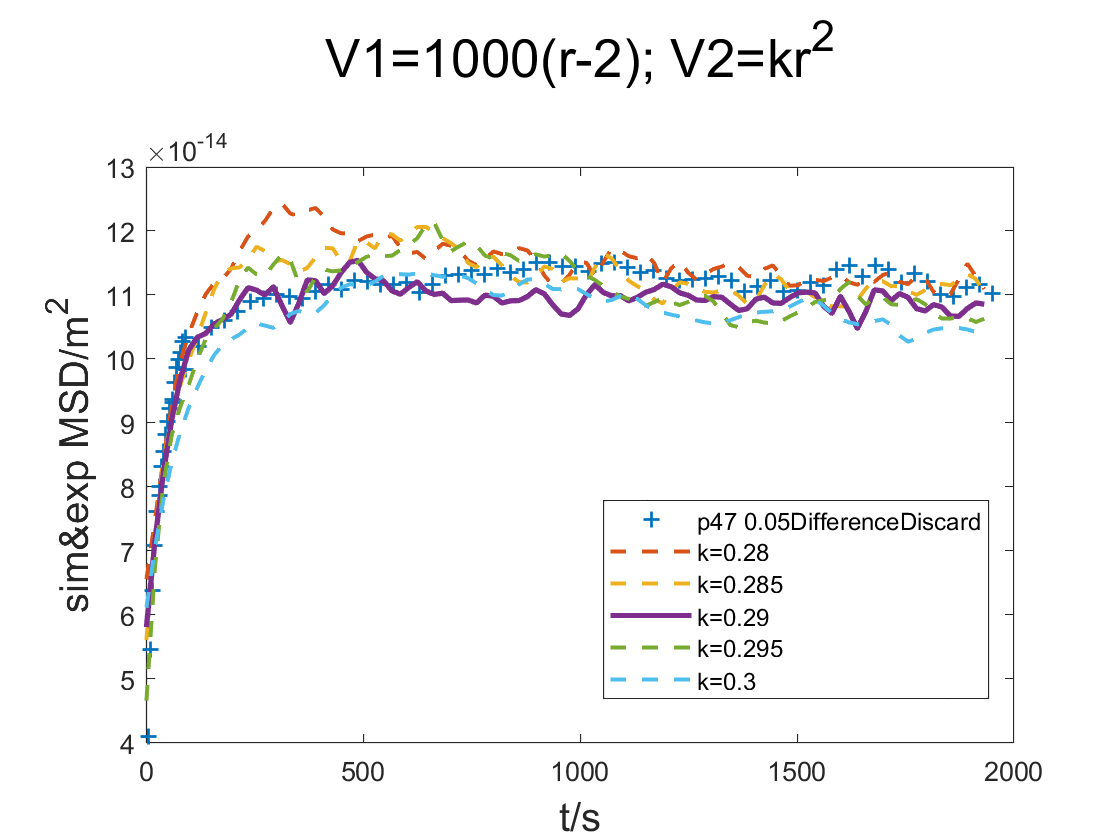

figure
%subplot(1,2,2);
plot(t_exp,MSD_exp*1e-18,'+','LineWidth',1,'DisplayName',expMSDType)
hold on
for simParameterNumber=1:length(simParameterList)
    if simParameterNumber==3
        plot(1:max(t_exp)/100:max(t_exp),sim_list(simParameterNumber,:),'DisplayName',['k=',num2str(simParameterList(simParameterNumber))],'LineWidth',2)
    else
        plot(1:max(t_exp)/100:max(t_exp),sim_list(simParameterNumber,:),'--','DisplayName',['k=',num2str(simParameterList(simParameterNumber))],'LineWidth',1.5)
    end
end
title({simMSDType;''},"FontSize",20)
xlabel('t/s',"FontSize",15)
ylabel('sim&exp MSD/m^2',"FontSize",15)
%set(gca,'yscale','log')
legend('Location',"best")